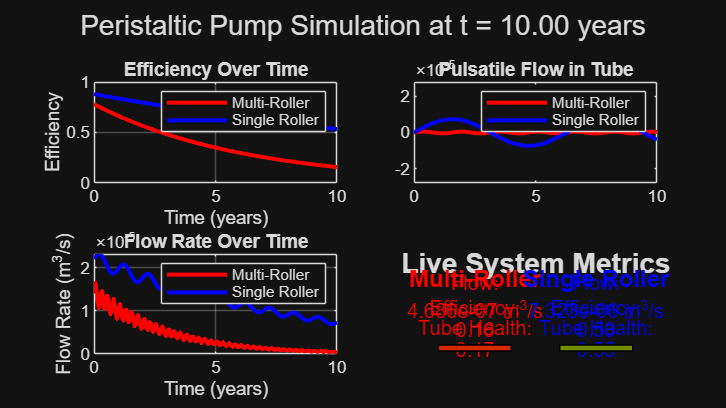

clc; clear; close all;

% TIME
t_years = linspace(0,10,150);
t = t_years * 365 * 24 * 3600;

% PUMP CONFIGURATION
% Pump and geometry parameters for multi- and single-roller configurations
rollers_multi = 4;
rollers_single = 1;
% Rotational speed (rad/s) from rpm
rpm = 60;
omega = rpm/60 * 2*pi;
% Volumetric displacement per revolution (m^3)
V_disp_multi = 1.8e-5;
V_disp_single = 2.5e-5;
% Nominal mechanical efficiencies (unitless)
eta_multi_0 = 0.78;
eta_single_0 = 0.88;
% Efficiency sensitivity coefficients (used in loss models)
k_multi = 0.16;
k_single = 0.05;
% Effective flow area or contact area (m^2)
A_multi = 0.20;
A_single = 0.08;
% Tube/line decay (attenuation) coefficients (per meter)
tube_decay_multi = 0.18;
tube_decay_single = 0.06;

% PREALLOCATE
% Preallocate vectors for eta, Q, and tube_health for speed
eta_multi = zeros(size(t));
eta_single = zeros(size(t));
Q_multi = zeros(size(t));
Q_single = zeros(size(t));
tube_health_multi = zeros(size(t));
tube_health_single = zeros(size(t));

% VIDEO SETUP
% Create MPEG-4 video writer file and set frame rate
v = VideoWriter('peristaltic_pump_simulation.mp4','MPEG-4');
v.FrameRate = 24;
open(v);
% Open figure window sized 1280x720 for video frame capture
figure('Position',[100 100 1280 720]);

% SIMULATION LOOP
for i = 1:length(t)
    
    % ---- Efficiency ----
    eta_multi(i) = eta_multi_0 * exp(-k_multi*t_years(i));
    eta_single(i) = eta_single_0 * exp(-k_single*t_years(i));
    
    % ---- Tube health ----
    tube_health_multi(i) = exp(-tube_decay_multi*t_years(i));
    tube_health_single(i) = exp(-tube_decay_single*t_years(i));
    
    % ---- Flow ----
    % Compute average flow from displacement, RPM and efficiency
    Q_avg_multi = V_disp_multi * rpm/60 * eta_multi(i);
    Q_avg_single = V_disp_single * rpm/60 * eta_single(i);
    
    % Modulate average flow by oscillatory roller effect and tube health
    Q_multi(i) = Q_avg_multi * ...
        (1 + A_multi*sin(rollers_multi * omega * t(i))) * ...
        tube_health_multi(i);
    
    Q_single(i) = Q_avg_single * ...
        (1 + A_single*sin(rollers_single * omega * t(i))) * ...
        tube_health_single(i);
    
    % Prevent negative flows (clamp to zero)
    Q_multi(i) = max(Q_multi(i), 0);
    Q_single(i) = max(Q_single(i), 0);

    % 1. Efficiency
    subplot(2,2,1)
    plot(t_years(1:i), eta_multi(1:i),'r','LineWidth',2); hold on;
    plot(t_years(1:i), eta_single(1:i),'b','LineWidth',2); hold off;
    
    title('Efficiency Over Time');
    xlabel('Time (years)');
    ylabel('Efficiency');
    legend('Multi-Roller','Single Roller');
    grid on;
    xlim([0 10]); ylim([0 1]);

    % 2. Flow Animation
    subplot(2,2,2)
    x = linspace(0,10,200);
    
    wave_multi = Q_multi(i) * sin(rollers_multi * (x - omega*t(i)));
    wave_single = Q_single(i) * sin(rollers_single * (x - omega*t(i)));
    
    plot(x, wave_multi,'r','LineWidth',2); hold on;
    plot(x, wave_single,'b','LineWidth',2); hold off;
    
    title('Pulsatile Flow in Tube');
    legend('Multi-Roller','Single Roller');
    
    ylim([-1.2*max([Q_multi Q_single]) 1.2*max([Q_multi Q_single])]);

    % 3. Flow Rate
    subplot(2,2,3)
    plot(t_years(1:i), Q_multi(1:i),'r','LineWidth',2); hold on;
    plot(t_years(1:i), Q_single(1:i),'b','LineWidth',2); hold off;
    
    title('Flow Rate Over Time');
    xlabel('Time (years)');
    ylabel('Flow Rate (m^3/s)');
    legend('Multi-Roller','Single Roller');
    grid on;
    xlim([0 10]);

    % 4. DASHBOARD (CLEAN)
    subplot(2,2,4)
    cla;
    axis([0 1 0 1])
    axis off
    hold on
    
    % Title
    text(0.5,0.90,'Live System Metrics', ...
        'HorizontalAlignment','center',...
        'FontSize',14,'FontWeight','bold');
    
    % Headers
    text(0.25,0.75,'Multi-Roller','Color','r',...
        'FontSize',12,'FontWeight','bold','HorizontalAlignment','center');
    
    text(0.75,0.75,'Single Roller','Color','b',...
        'FontSize',12,'FontWeight','bold','HorizontalAlignment','center');
    
    % Metrics
    text(0.25,0.55,sprintf('Flow:\n%.3e m^3/s', Q_multi(i)),...
        'Color','r','HorizontalAlignment','center');
    
    text(0.75,0.55,sprintf('Flow:\n%.3e m^3/s', Q_single(i)),...
        'Color','b','HorizontalAlignment','center');
    
    text(0.25,0.35,sprintf('Efficiency:\n%.2f', eta_multi(i)),...
        'Color','r','HorizontalAlignment','center');
    
    text(0.75,0.35,sprintf('Efficiency:\n%.2f', eta_single(i)),...
        'Color','b','HorizontalAlignment','center');
    
    text(0.25,0.15,sprintf('Tube Health:\n%.2f', tube_health_multi(i)),...
        'Color','r','HorizontalAlignment','center');
    
    text(0.75,0.15,sprintf('Tube Health:\n%.2f', tube_health_single(i)),...
        'Color','b','HorizontalAlignment','center');
    
    % Health bars
    rectangle('Position',[0.10 0.03 0.30 0.06],...
        'FaceColor',[1-tube_health_multi(i), tube_health_multi(i), 0], ...
        'EdgeColor','k');

    rectangle('Position',[0.60 0.03 0.30 0.06],...
        'FaceColor',[1-tube_health_single(i), tube_health_single(i), 0], ...
        'EdgeColor','k');

    hold off

    sgtitle(sprintf('Peristaltic Pump Simulation at t = %.2f years', t_years(i)));

    drawnow;
    frame = getframe(gcf);
    writeVideo(v, frame);
end


close(v);

fprintf('\nFlow Variability (Multi): %.6e\n', std(Q_multi));


Flow Variability (Multi): 3.762420e-06


fprintf('Flow Variability (Single): %.6e\n', std(Q_single));

Flow Variability (Single): 4.380206e-06



fprintf('\nTotal Volume (Multi): %.6e m^3\n', trapz(t, Q_multi));


Total Volume (Multi): 1.261402e+03 m^3


fprintf('Total Volume (Single): %.6e m^3\n', trapz(t, Q_single));

Total Volume (Single): 4.213538e+03 m^3



disp('Video saved as peristaltic_pump_simulation.mp4');

Video saved as peristaltic_pump_simulation.mp4
